# Taller 2

clear


## Propiedades del motor

Kt = 1.57e-2*1;Ke = Kt;
Ra = 8*0.8;
B = 2.52e-3*1.2;
J = 9.85e-3*1.2;
m=0.3*1;
d=0.05*1.2;
g=9.81;

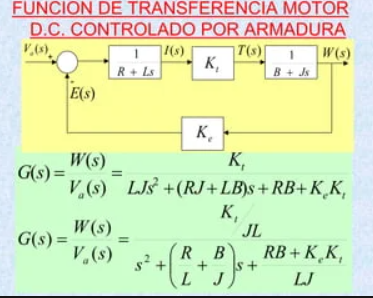

### Definición inductancia

s=tf('s');
PoloSM=pole(1/(B+J*s))

PoloSM = -0.2558

#### Inductancia infinitamente pequeña

%L=5e-5
%PoloSE=pole(1/(Ra+L*s))
%gan=1.236e-1 %Pse<<Psm
%Go=gan/(L+Ra*gan)

#### Inductancia "pequeña"

L=Ra/(B/J*10)

L = 2.5016

PoloSE=pole(1/(Ra+L*s))

PoloSE = -2.5584

gan=45  %Pe=-5Pm

gan = 45

### Sistema eléctrico Simplificado

Go=gan/(L+Ra*gan)

Go = 0.1549

Go=0.125

Go = 0.1250

### Sistema Pol grado 5

Gp=Go*Kt*(1/(J*s)/(1+B/(J*s)));
Gpo=Gp/(1+Gp*Ke)

Gpo =
 
          2.593e-09 s^3 + 6.633e-10 s^2
  ---------------------------------------------
  1.952e-08 s^4 + 1.002e-08 s^3 + 1.286e-09 s^2
 
Continuous-time transfer function.



### Sistema Pol grado 3

Num=Gpo.Numerator{1}(1:3)

Num = 1.0e-08 *

         0    0.2593    0.0663


Den=Gpo.Denominator{1}(1:3)

Den = 1.0e-07 *

    0.1952    0.1002    0.0129


## Controlador

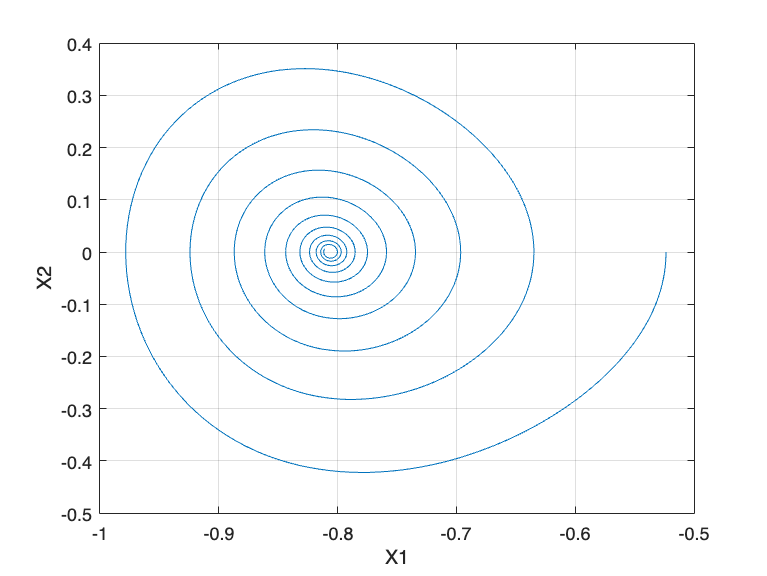

delta=30*(pi/180);
cond_init=0*(pi/180);


% Parámetros de SMC 
a       = 1;
beta    = 100;

sim("SMCsimplificado.slx");
simout=ans;

figure(1)
plot(simout.X.Data(:,3),simout.X.Data(:,2))
grid on
xlabel("X1")
ylabel("X2")

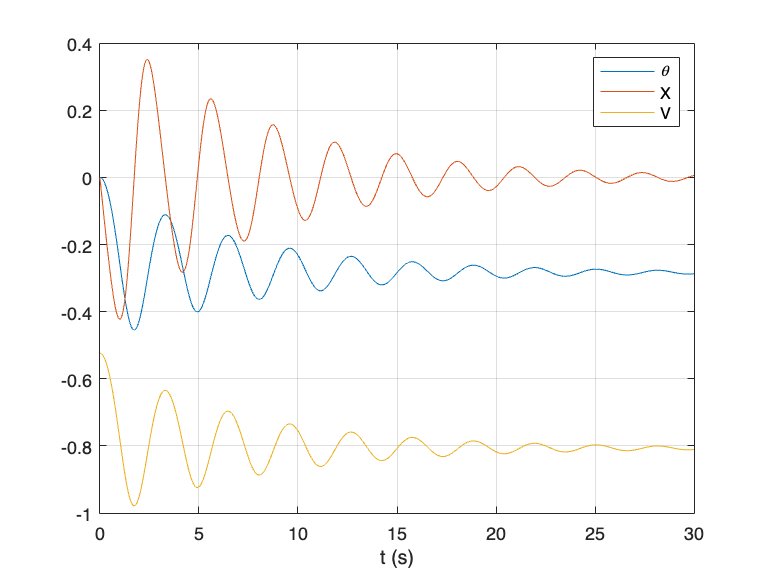


figure(2)
plot(simout.X.Time,simout.X.Data)
legend("\theta","X","V")
xlabel("t (s)")
grid on

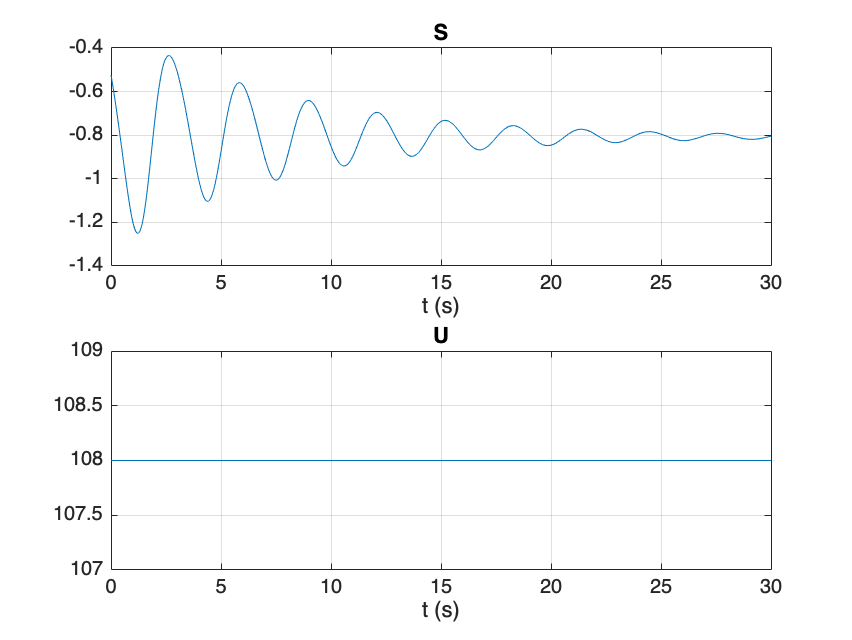


figure(3)
subplot(2,1,1)
plot(simout.S.Time,simout.S.Data)
title("S")
xlabel("t (s)")
grid on
subplot(2,1,2)
plot(simout.U.Time,simout.U.Data)
title("U")
xlabel("t (s)")
grid on

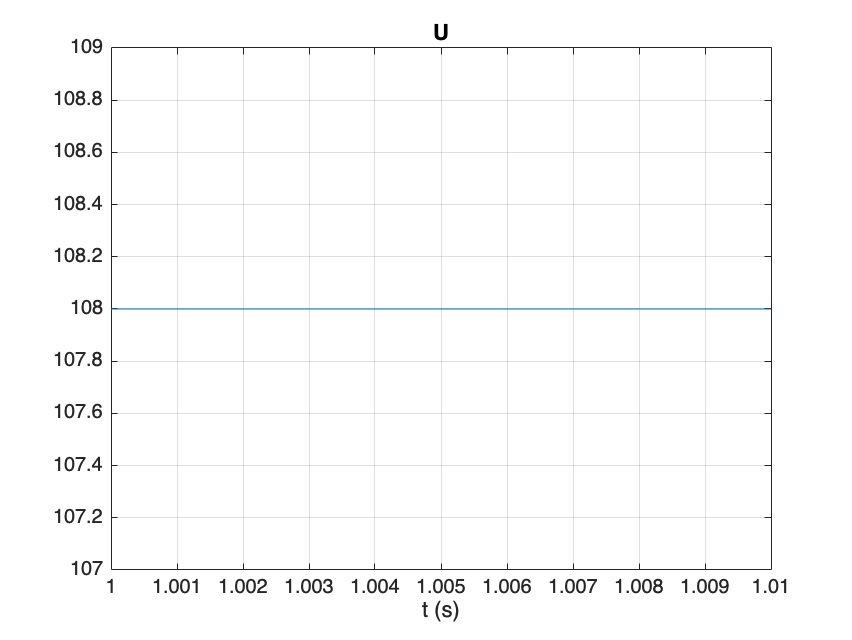


figure()
plot(simout.U.Time,simout.U.Data)
title("U")
xlabel("t (s)")
xlim([1 1.01])
grid on


t=simout.U.Time(1:(end-1))

t =          0
    0.0002
    0.0013
    0.0066
    0.0266
    0.0466
    0.0666
    0.0866
    0.1066
    0.1266


x=simout.U.Data(1:(end-1))

x =    108
   108
   108
   108
   108
   108
   108
   108
   108
   108


L=length(t)

L = 1619030

Y=fft(x,L)

Y = 1.0e+08 *

   3.6341 + 0.0000i
   0.0110 - 0.0019i
   0.0101 - 0.0037i
   0.0087 - 0.0052i
   0.0072 - 0.0062i
   0.0055 - 0.0069i
   0.0037 - 0.0067i
   0.0017 - 0.0060i
   0.0006 - 0.0050i
  -0.0004 - 0.0037i


T=t(2)-t(1)

T = 4.0188e-06

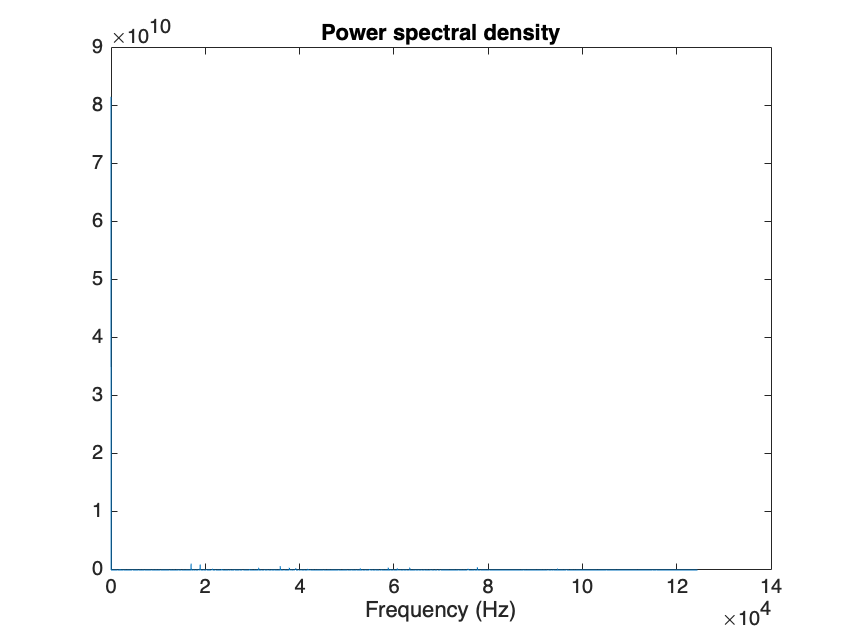


Fs=T^-1;

Pyy = Y.*conj(Y)/L;
f = Fs*(0:(L/2))/L;
P1 = Pyy(1:L/2+1);
plot(f,P1)
title('Power spectral density')
xlabel('Frequency (Hz)')

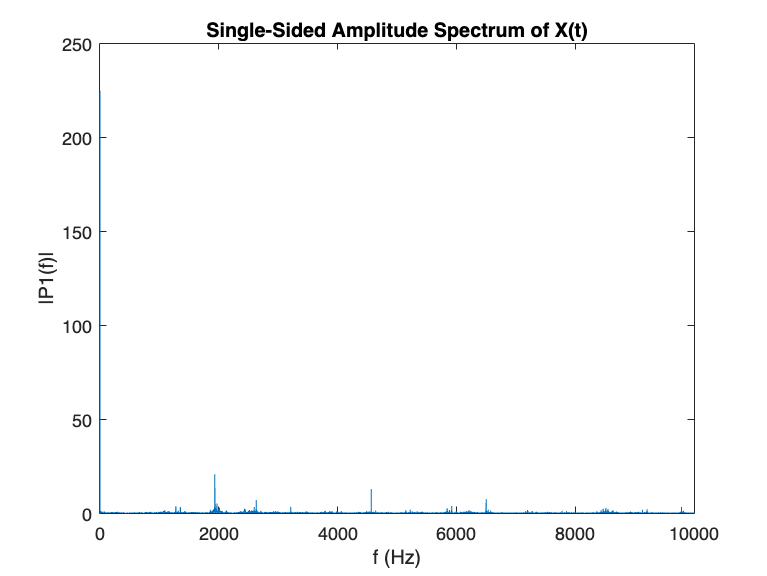


P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);


figure()
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')
xlim([0 10000])


[pks,locs] = findpeaks(x);
periods = diff(locs) / Fs;
freq = 1 / mean(periods)

freq = 2.2313e+04

## Calculo de beta

a = 1

a = 1

b_vals = []; 
theta = []; 


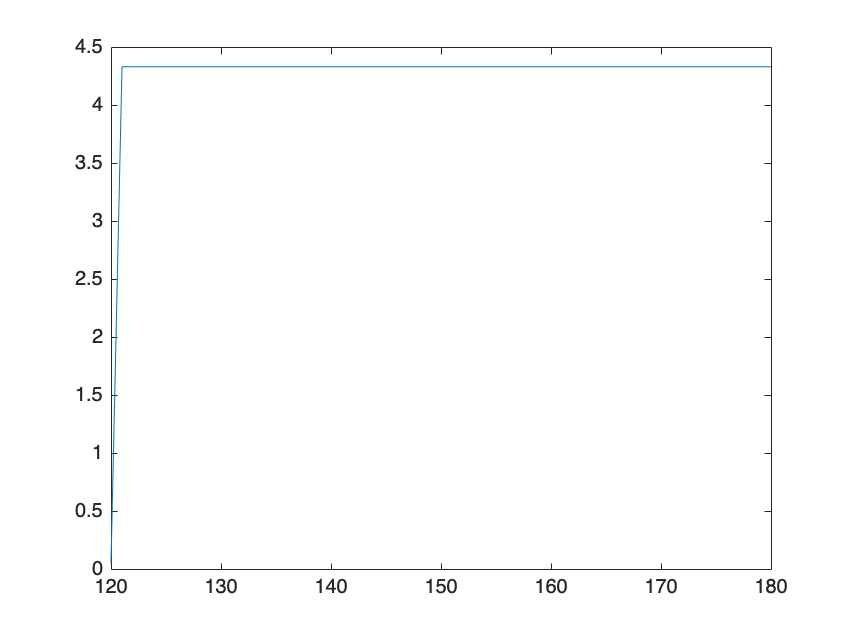


max_vals = []; 
int = 120:180; 
for i = int
    for x2_crit = linspace(-pi/2, pi/2, i)
        b = ( J * a * x2_crit + Go * Kt) / ((Go * Kt * Ke + B) * x2_crit  + m * g * d * J * cos(0)); 
        theta = [theta, x2_crit]; 
        b = abs(b);
        b_vals = [b_vals, b]; 
    end 
    m = max(b_vals);
    max_vals = [max_vals, m];
end 

plot(int, max_vals)

## Control equivalente

Modelo afín: 


$$\begin{array}{l}
g\left(x\right)=\frac{1}{J}\left({G_o K}_t \right)\\
h\left(x\right)=-\frac{1}{J}\;\left({G_{\prime 0} K}_t K_e +B\right)x_2 +m\;g\;d\;\cos \left(x_1 \right)
\end{array}$$


% valores nominales 
Kt_hat = 1.57e-2;
Ke_hat = Kt_hat;
Ra_hat = 8; 
B_hat = 2.52e-3; 
J_hat = 9.85e-3; 
m_hat= 0.3; 
d_hat= 5e-2; 

Go_hat = 1 / Ra_hat; 

% parametros SMC 
% a = 1; 

% estados criticos 
x1_crit = pi;    % [-pi, pi]
x2_crit = pi/2; % [-pi/2, pi/2]

% funciones nominales 
h_hat = -1/J_hat * (Go_hat * Kt_hat * Ke_hat + B_hat) * x2_crit + m_hat * g * d_hat * cos(x1_crit); 
g_hat = 1/J * (Go_hat * Kt_hat)

g_hat = 0.1660


% accion de control 
coef1  = -(a) /(g_hat);
coef2  = -(h_hat) /(g_hat); 

coef1 = round(coef1, 1); 
coef2 = round(coef2, 1); 

% Accion de control equivalente 
disp(num2str(coef1) + " x2 + " + num2str(coef2) + " cos x1")

-6 x2 + 3.3 cos x1


## Accion de control total